# C&PE 778 Homework 06                                 William Powers 2025

#### ***1. Solve the following MILP problem using the bound-and-branch algorithm.***


$$\max z = x_2 + 4x_3$$



$$\text{s.t}$$



$$3x_1-6x_2+9x_3 - 9\le 0$$



$$3x_1+2x_2+x_3 - 7 \le 0$$



$$x_1, x_2, x_3 \in \{0, 1, 2, 3, ...\}$$


The root-node (LP relaxation) of the problem is first formed and then solved using the simplex method. Here the relaxation is allowing the discrete values of $\mathbf{x}$ to take on continuour values in order to provide a upper bound to the problem.


$$\max z = x_2 + 4x_3$$



$$\text{s.t}$$



$$3x_1-6x_2+9x_3 - 9\le 0$$



$$3x_1+2x_2+x_3 - 7 \le 0$$



$$x_1, x_2, x_3 \ge 0$$


% objective coefficients, inequality constraints
f = -1 * [0 1 4]; A = [ 3  -6   9; 3   2   1]; b = [9; 7];

% variable bounds
lb = [0 0 0];
ub = [inf inf inf];

%  solve via matlab simplex algorithm
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

         0
    2.2500
    2.5000

   12.2500



The maximum value to the root-node is used as the problems optimal upper bound. Neither $x_2$ and $x_3$ is discrete in this solution therefore they are both considered as the branch variables.

Branching on variable $x_2$ yeilds (evaluated using the code excerpt after the image).

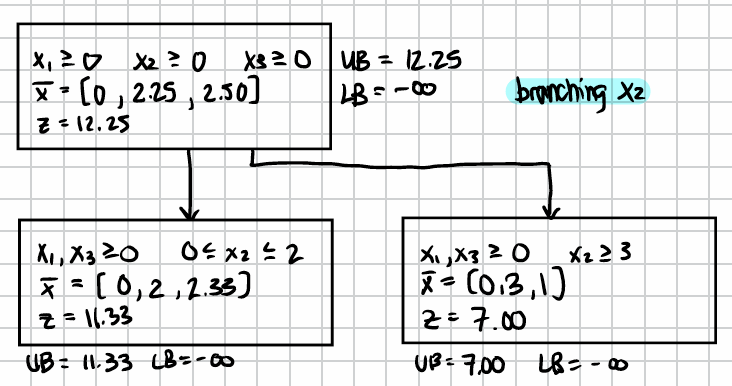

% branch with 0 <= x_2 <= 2
lb = [0 0 0];
ub = [inf 2 inf];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

         0
    2.0000
    2.3333

   11.3333




% branch with x_2 >= 3
lb = [0 3 0];
ub = [inf inf inf];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

     0
     3
     1

     7



Branching on variable $x_3$ yeilds (evaluated using the code excerpt after the image).

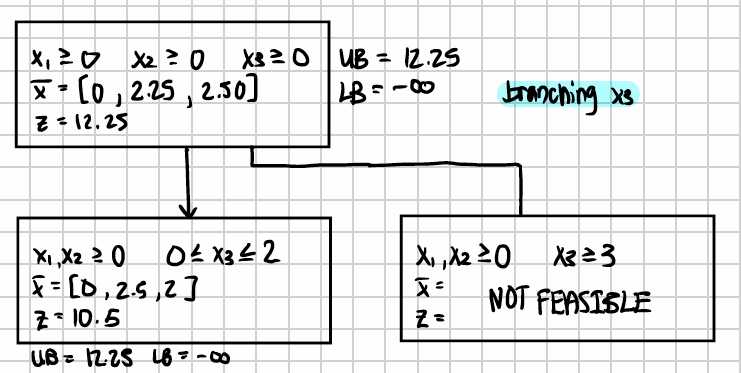

% branch with 0 <= x_3 <= 2
lb = [0 0 0];
ub = [inf inf 2];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

         0
    2.5000
    2.0000

   10.5000




% branch with x_3 >= 3
lb = [0 0 3];
ub = [inf inf inf];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


No feasible solution found.

Linprog stopped because no point satisfies the constraints.



disp(x_opt); disp(-1*fval);

Becuase no feasible discrete solution has been found at the current tree level, the branching process is continued. As the solution with $x_1, x_3 \ge 0$ and $0 \ge x_2 \ge 2$ provided the largest UB, the first branch is made here which provides a feasible solution with new LB =$10.00$.

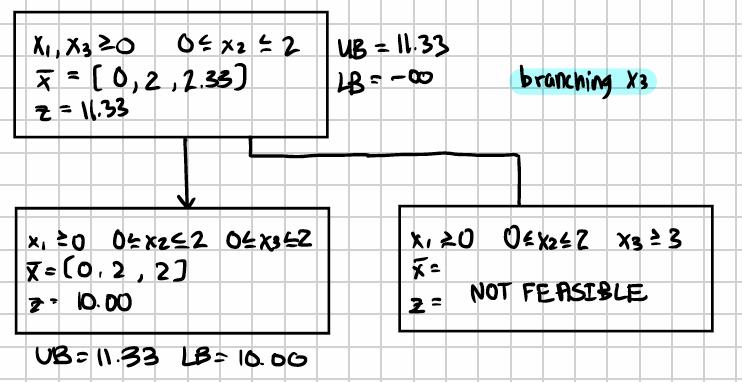

% branch with x_1 >= 0, 0 <= x_2, x_3 <= 2
lb = [0 0 0];
ub = [inf 2 2];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

     0
     2
     2

    10




% branch with x_1 >= 0, 0 <= x_2 <= 0, x_3 >= 3
lb = [0 0 3];
ub = [inf 2 inf];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


No feasible solution found.

Linprog stopped because no point satisfies the constraints.



disp(x_opt); disp(-1*fval);

The previous solution fathomes all nodes with a UB less than this new highest LB of $10.00$ leaving only one node branching left to check. From the results shown below we can see that although this branch does produce a feasible solution, previously evaluated feasible node with solution $10.00$ is still larger. All other nodes are now implicitly fathomed leaving this as the optimal integer valued solution.

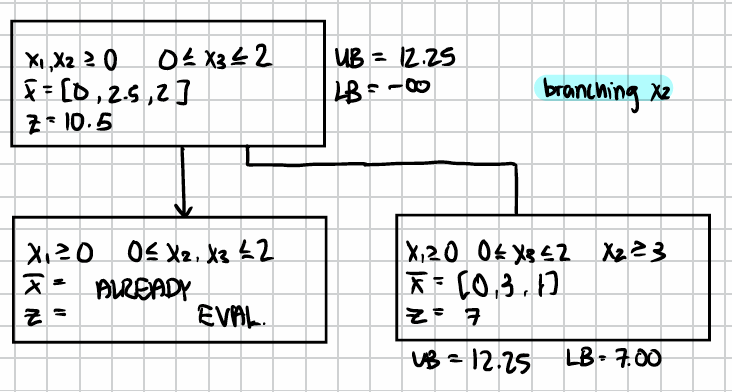

% branch with x_1 >= 0, 0 <= x_2, x_3 <= 2
% ALREADY EVALUATED x = [0, 2, 2], z = 10.00

% branch with x_1 >= 0, x_2 >= 3, 0 <= x_3 <= 0
lb = [0 3 0];
ub = [inf inf 2];
options = optimoptions('linprog','Algorithm','dual-simplex');
[x_opt, fval] = linprog(f, A, b, [], [], lb, ub, options);


Optimal solution found.



disp(x_opt); disp(-1*fval);

     0
     3
     1

     7

